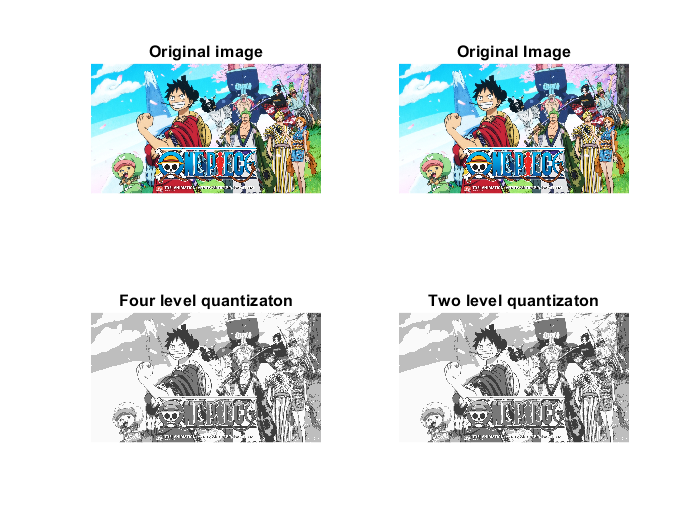

close all;
clear all;
clc;
I= imread('C:\Users\Sandeep\Downloads\onepiecergb.jpe');
subplot(221) ; imshow(I); title("Original image");
gray = rgb2gray(I);
subplot(222); imshow(I); title("Original Image");
FG= gray;
[r,c] = size(FG);
for i=1: r
    for j=1 :c
        f=FG(i,j);
        if f<=64
            FG(i,j) = 60;
        elseif f>65 && f<=128
            FG(i,j) =120;
        elseif f>128 && f<=192
            FG(i,j)= 190;
        elseif f>192 && f<256
            FG(i,j)=250;
        end
    end
end
subplot(223);imshow(FG); title("Four level quantizaton")

[r,c] = size(gray);
for i=1: r
    for j=1 :c
        f=gray(i,j);
        if f<=127
            gray(i,j) = 0;
       
        elseif f>127 && f<255
            gray(i,j)=250;
        end
    end
end
subplot(224);imshow(FG); title("Two level quantizaton")